% 执行区间长度变化，选择simga u 均未知，对u进行估计的情形
u       = 1

u =      1


sig     = 1

sig =      1


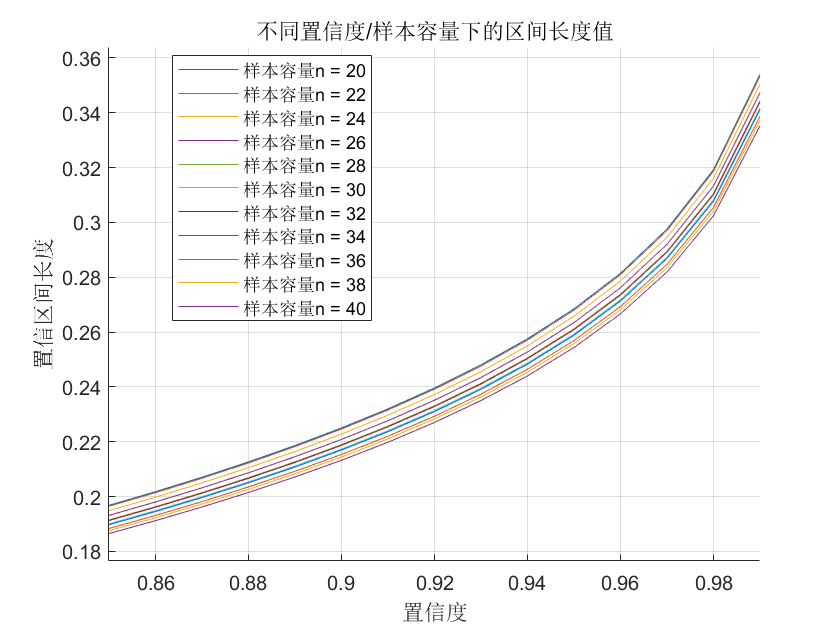

% 样本容量固定为25，p 从 0.85 变化到 0.99
ps = 0.85:0.01:0.99;
lens = zeros(11, 15);
sample = normrnd(u, sig, 1, 240);
for n = 220:2:240
    cnt = 1;
    for p = 0.85:0.01:0.99
        lens((n - 218)/2, cnt) = intervalLen(sample(1:n), p);
        cnt = cnt + 1;
    end
end
hold on; 
str_mat = strings(1, 11);
for n = 1:11
    plot(ps, lens(n, :));
    str_mat(n) = sprintf("样本容量n = %d", n * 2 + 18);
end
axis on; grid on;
xlim([0.85, 0.99]);
ylim([min(min(lens)) - 0.01, max(max(lens)) + 0.01]);
legend(str_mat, 'Location','best');
xlabel("置信度");
ylabel("置信区间长度");
title("不同置信度/样本容量下的区间长度值");

function len = intervalLen(spl, prob)
% 求正态总体u，sigma未知时，u的置信区间长度
% spl 样本值向量
% prob 置信度
    n = length(spl);
    bound = tinv(0.5 + 0.5 * prob, n - 1);    % t(n-1) 的上分位数
    spl_std = std(spl);
    len = 2 * spl_std / sqrt(n) * bound;
end